# INTERPOLACJA

## SPLINE

**ĆWICZENIE 1:**

W ćwiczeniu 1 wykorzystamy i zanalizujemy prosty algorytm obliczający spline liniowy. 

Spline liniowy korzysta ze zbyt prostych funkcji, żeby zastosować podejście bardziej zaawansowane, które będzie pokazane w ćwiczeniu 2. W tym sensie jest to spline ponieważ rozwiązanie składa się z wielu funkcji - każda określona w kolejnym podprzedziale i tworzą one razem funkcję ciągłą przechodzącą przez wszystkie węzły. Niemniej brak możliwości kształtowania bardziej zaawansowanych cech tej interpolacji powoduje, że raczej niezbyt dobrze oddaje kształt krzywej pomiędzy węzłami.

Spline liniowy polega na połączeniu po prosu każdych dwóch punktów za pomocą odcinka linii prostej. Z matematycznego punktu widzenia możemy to opisać następującym równaniem:


$$y=\frac{y_{i+1} -y_i }{x_{i+1} -x_i }\left(x-x_i \right)+y_i$$


Nasz zaimplementowany algorytm działa następująco:

% Najpierw wygenerujmy węzły 
% Zdefiniujmy prostą funkcję w której będą 3 podprzedziały - niech będzie to
% y=exp(x)+1
f=@(x) exp(x)+1;

% Skoro chcemy mieć 3 podprzedziały to musimy mieć 4 punkty:
x=[1 2 3 4];
y=f(x);

% Narysujmy sobie naszą sytuację:
figure(1);
xx=linspace(min(x),max(x),401);
plot(x,y,'ob',xx,f(xx),'k--');grid on; hold on;
for i=x 
    xline(i, 'r--'); end; hold on;

% Prosta implementacja spline liniowego w oparciu o podany wyżej wzór:
syms xxx

S1=(y(2)-y(1))./(x(2)-x(1)).*(xxx-x(1))+y(1)

$$S1 = 4.6708\,\mathrm{xxx}-0.9525$$

S2=(y(3)-y(2))./(x(3)-x(2)).*(xxx-x(2))+y(2)

$$S2 = 12.6965\,\mathrm{xxx}-17.0039$$

S3=(y(4)-y(3))./(x(4)-x(3)).*(xxx-x(3))+y(3)

$$S3 = 34.5126\,\mathrm{xxx}-82.4523$$

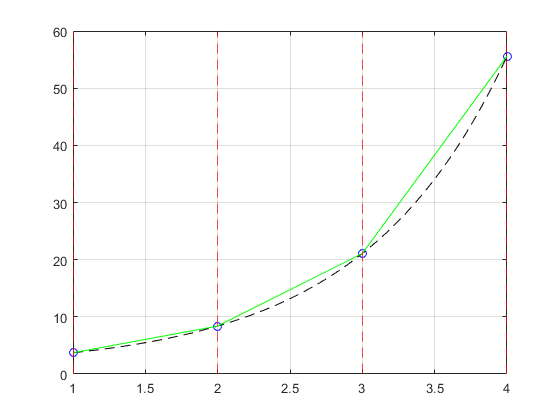


% Dorysujemy nasz spline na wykresie
s1=matlabFunction(S1);
s2=matlabFunction(S2);
s3=matlabFunction(S3);

figure(1);
xxx=[x(1):0.01:x(2)];
plot(xxx,s1(xxx),'g');hold on;
xxx=[x(2):0.01:x(3)];
plot(xxx,s2(xxx),'g');hold on;
xxx=[x(3):0.01:x(4)];
plot(xxx,s3(xxx),'g');hold off;

**ĆWICZENIE 2:**

W tym ćwiczeniu użyjemy własnej zaimplementowanej "na piechotę" funkcji implementującej klasyczny spline kubiczny. Podejrzymy sobie jak wygląda macierz układu równań i jak będzie rozwiązywana.

Choć przedyskutowaliśmy teorię dotyczącą splineów to same implementacje typowych metod typu spline zazwyczaj są uproszczone w stosunku do ogólnej teorii (podobnie jak w przypadku implementacji interpolacji np. Lagrange'a nie było potrzeby rozwiązywania jawnie układu równań).

Również w przypadku spline kubicznego istnieje kilka sposobów samej implementacji tej metody. My zastosujemy tutaj metodę opartą o drugie pochodne.

Przypomnijmy sobie jakie wymogi stawia przed nami spline kubiczny (naturalny):

1. W każdym i-tym podprzedziale funkcja interpolująca musi przechodzić przez węzły:


$$S_i \left(x_{i-1} \right)=y_{i-1}$$



$$S_i \left(x_i \right)=y_i$$


Zwróć uwagę, ze spline kubiczny nie jest splinem prostym. W odróżnieniu od poprzedniego przykładu jego budowa jest inna - mimo, że każdy podprzedział będzie zawierał wielomian 3 stopnia to w każdym podprzedziale są tylko dwa punkty (a nie trzy jak wynikałoby to ze splinu prostego)

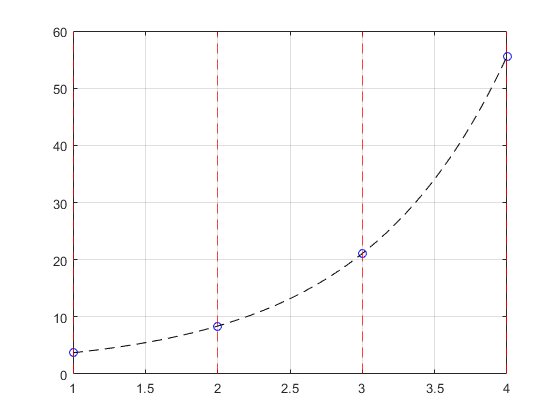

%Zdefiniujmy prostą funkcję w której będą 3 podprzedziały - niech będzie to
%y=exp(x)+1
f=@(x) exp(x)+1;

%Skoro chcemy mieć 3 podprzedziały to musimy mieć 4 punkty:
x=[1 2 3 4];
y=f(x);

%Narysujmy sobie naszą sytuację:
xx=linspace(min(x),max(x),401);
plot(x,y,'ob',xx,f(xx),'k--');grid on; hold on;
for i=x 
    xline(i, 'r--'); end; hold off;

2. W przypadku splineu kubicznego wymagamy, aby pierwsza i druga pochodna na krańcach przedziału były sobie równe:


$$S_i^{\left(1\right)} \left(x_i \right)=S_{i+1}^{\left(1\right)} \left(x_i \right)$$



$$S_i^{\left(2\right)} \left(x_i \right)=S_{i+1}^{\left(2\right)} \left(x_i \right)$$


Warunek brzegowy na razie zostawimy. Zamiast budować macierz pełną liczb w standardowy sposób zapisując w każdym wierszu każdy z tych warunków dla każdego z punktów możemy zbudować od razu macierz diagonalnie dominującą jeżeli zauważymy, że druga pochodna funkcji kubicznej to linia prosta o jakichś nieznanych wartościach  w węzłach interpolacji. Wartości tej pochodnej  są nieznane, ale możemy zrobić z nich nasza główną niewiadomą. Taki wybieg gwarantuje, że powstająca macierz ma budowę diagonalną.

Weźmy przykładowy przedział  $\left\lbrack x_{i-1} ,x_i \right\rbrack$ - nasza druga pochodna będzie w tym przedziale przyjmowała wartości  $M_{i-1} ,M_i$

Aby to zobrazować wykonajmy następujący kod który wyciągnie z rozwiązania zaimplementowanego w MATLAB odpowiednie liczby. Normalnie oczywiście nie znamy tych współczynników:

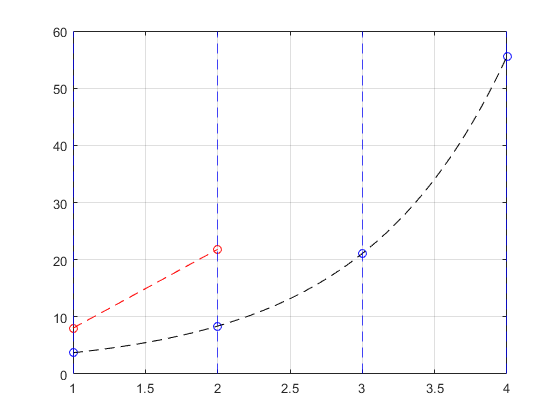

% Wykonajmy spline zaimplementowany w MATLABie
%struct = spline(x,y);
struct = interp1(x,y,'spline','pp');

% Współczynniki wielomianu dla pierwszego przedziału to:
wsp = struct.coefs(1,1:end);

% Obliczamy 2 pochodną
sndDeriv = polyder(polyder(wsp));

% Wartość M0 i M1 dla pierwszego przedziału to:
xx=linspace(min(x),max(x),401);
plot(x,y,'ob',xx,f(xx),'k--');grid on; hold on;
for i=x 
    xline(i, 'b--'); end;
plot(x(1:2),polyval(sndDeriv, x(1:2)),'ro');
plot(x(1:2),polyval(sndDeriv, x(1:2)),'r--');hold off;

Zakładając chwilowo, że znamy $M_0 ,M_1$ wzór na prostą (2 pochodną) moglibyśmy wyznaczyć za pomocą prostej interpolacji wielomianowej np. interpolacji Lagrange'a:


$$S_1^{\left(2\right)} \left(x\right)=M_0 \frac{x_1 -x}{h}+M_1 \frac{x-x_0 }{h}$$


taką prostą zaznaczyliśmy na rysunku na czerwono. Ogólnie dla dowolnego przedziału:


$$S_i^{\left(2\right)} \left(x\right)=M_{i-1} \frac{x_i -x}{h}+M_i \frac{x-x_{i-1} }{h}$$


Całkując to wyrażenie dwukrotnie i korzystając z warunku przechodzenia przez punkty w przedziale $S_i \left(x_{i-1} \right)=y_{i-i}$ oraz $S_i \left(x_i \right)=y_i$ uzyskujemy:


$$S_i \left(x\right)=M_{i-1} \frac{{\left(x_i -x\right)}^3 }{6h_i }+M_i \frac{{\left(x-x_{i-1} \right)}^3 }{6h_i }+\left(y_{i-1} -\frac{M_{i-1} h_i^2 }{6}\right)\frac{x_i -x}{h_i }+\left(y_i -\frac{M_i h_i^2 }{6}\right)\frac{x-x_{i-1} }{h_i }$$
 

Jeżeli znalibyśmy wszystkie $M_i$ to moglibyśmy obliczyć funkcję spline. 

Zwróć uwagę, że nie uwzględniliśmy tutaj na razie żadnych warunków ciągłości itd. To dlatego, że dopiero formujemy równania które wykorzystamy przy budowie układu równań do rozwiązania. Układ ten jednak będzie rozwiązywany ze względu na  a nie typowe współczynniki interpolacyjne. Taka implementacja jest jedną z najczęściej wykorzystywanych bo w odróżnieniu od podstawowej generuje macierz diagonalnie dominującą. Na koniec przekształcimy ją do postaci podstawowej i obejrzymy różnice między tymi postaciami.

Dla wszystkich punktów poza skrajnymi musimy uwzględnić warunek ciągłości pierwszej pochodnej. Wzór na pierwszą pochodną wyprowadzamy również przez całkowanie 2 pochodnej. W przedziale [$x_{i-1}$,$x_i$]:


$$S_i^{\left(1\right)} \left(x\right)=-M_{i-1} \frac{{\left(x_i -x\right)}^2 }{2h_i }+M_i \frac{{\left(x-x_{i-1} \right)}^2 }{2h_i }+\frac{y_i -y_{i-1} }{h_i }-\frac{M_i -M_{i-1} }{6}h_i$$


więc 


$$S_i^{\left(1\right)} \left(x_i \right)=$$

$$M_i \frac{h_i }{2}+\frac{y_i -y_{i-1} }{h_i }-$$

$$\frac{M_i -M_{i-1} }{6}h_i$$


W następnym przedziale [$x_i$,$x_{i+1}$] robimy analogiczną rzecz - wzory są te same, ale indeksy inne:


$$S_{i+1}^{\left(1\right)} \left(x\right)=-M_i \frac{{\left(x_{i+1} -x\right)}^2 }{2h_{i+1} }+M_{i+1} \frac{{\left(x-x_i \right)}^2 }{2h_{i+1} }+\frac{y_{i+1} -y_i }{h_{i+1} }-\frac{M_{i+1} -M_i }{6}h_{i+1}$$


oraz


$$S_{i+1}^{\left(1\right)} \left(x_i \right)=$$

$${-M}_i \frac{h_{i+1} }{2}+\frac{y_{i+1} -y_i }{h_{i+1} }-$$

$$\frac{M_{i+1} -M_i }{6}h_{i+1}$$


Poniższy kod pokazuje tę sytuację korzystając już z rozwiązania wygenerowanego przez funkcję wbudowaną MATLAB. Spróbuj zobaczyć jak sytuacja ma się dla dwóch pierwszych przedziałów i punktu je łączącego. Zwróć uwagę na indeksy - powyżej zaznaczono indeksację względną względem dowolnego przedziału i, poniżej mamy sprawę skonkretyzowaną

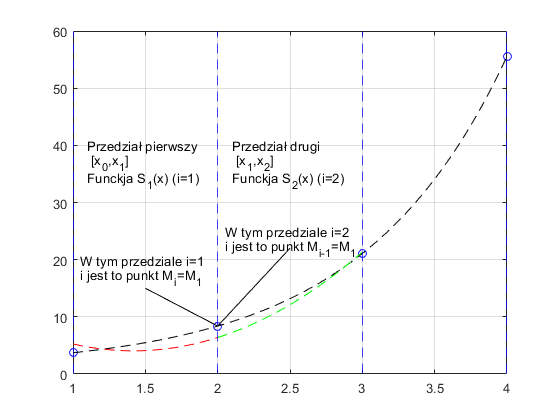

% Współczynniki wielomianu interpolującego w 2 przedziale
wsp2 = struct.coefs(2,1:end);

% Obliczamy pochodne
der1 = polyder(wsp);
der2 = polyder(wsp2);

% Rysujemy sytuację  opisaną powyżej dla dwóch pierwszych podprzedziałów
fig=figure(1);
xx=linspace(min(x),max(x),401);
plot(x,y,'ob',xx,f(xx),'k--');grid on; hold on;
for i=x 
    xline(i, 'b--'); end;

% Jeżeli chcesz wiedzieć dlaczego tak liczę pochodną zapoznaj się z
% dokumentacją funkcji spline (komenda doc spline)

xxx=[x(1):0.01:x(2)];
plot(xxx,der1(1).*(xxx-x(1)).^2+der1(2).*(xxx-x(1))+der1(3),'r--');
xxx=[x(2):0.01:x(3)];
plot(xxx,der2(1).*(xxx-x(2)).^2+der2(2).*(xxx-x(2))+der2(3),'g--');hold off;

% Opisy
text( 1.1, 40, 'Przedział pierwszy');
text( 1.1, 37, ' [x_{0},x_{1}]');
text( 1.1, 34, 'Funkcja S_{1}(x) (i=1)');

text( 2.1, 40, 'Przedział drugi');
text( 2.1, 37, ' [x_{1},x_{2}]');
text( 2.1, 34, 'Funkcja S_{2}(x) (i=2)');

ha=annotation('line');ha.Parent = fig.Children;
ha.X = [1.5 2];
ha.Y = [15 f(2)];
text( 1.05, 20, 'W tym przedziale i=1 ');
text( 1.05, 17, 'i jest to punkt M_{i}=M_{1}');

ha=annotation('line');ha.Parent = fig.Children;
ha.X = [2 2.5];
ha.Y = [f(2) 22];
text( 2.05, 25, 'W tym przedziale i=2 ');
text( 2.05, 22, 'i jest to punkt M_{i-1}=M_{1}');

Możemy teraz zapisać drugie wymaganie: $S_i^{\left(1\right)} \left(x_i \right)=S_{i+1}^{\left(1\right)} \left(x_i \right)$ - ciągłość pierwszej pochodnej na krańcach przedziału. Stąd dostajemy równanie:


$$\mu_i M_{i-1} +2M_i +\lambda_i M_{i+1} =d_i$$


gdzie:

$\mu_i =\frac{h_i }{h_i +h_{i+1} }$, $\lambda_i$=1-$\mu_i =\frac{h_{i+1} }{h_i +h_{i+1} }$, a $d_i =6f\left\lbrack x_{i-1} ,x_i ,x_{i+1} \right\rbrack$

To równanie zawiera w sobie już dwa wymagania: żeby wszystkie funkcje przechodziły przez węzły w swoich przedziałach oraz to, żeby pochodnej na stykach dwóch przedziałów były ciągłe. Możemy więc sformułować macierz zawierającą po jednym wierszu dla każdego z wewnętrznych punktów przedziału [a,b]:


$$\left\lbrack \begin{array}{ccccccc}
? & ? & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & ?\\
\mu_1  & 2 & \lambda_1  & 0 & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & 0\\
0 & \mu_2  & 2 & \lambda_2  & 0 & \ldotp \ldotp \ldotp  & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & \ddots  & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & \ddots  & \ddots  & \ddots  & \vdots \\
0 & \ddots  & \ddots  & \mu_{n-1}  & 2 & \lambda_{n-1}  & \vdots \\
0 & ? & \cdots  & \cdots  & \cdots  & ? & ?
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
M_0 \\
M_1 \\
M_2 \\
\vdots \\
\vdots \\
M_{n-1} \\
M_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
?\\
d_1 \\
d_2 \\
\vdots \\
\vdots \\
d_{n-1} \\
?
\end{array}\right\rbrack$$


Brakuje nam dwóch równań - dotyczą one punktów skrajnych i wynikają z przyjętych założeń dotyczących tego jak spline ma się zachowywać na brzegach przedziału.

W tym ćwiczeniu zajmujemy się spline naturalnym zatem warunek na wartości  krańcowe to:

3. W przypadku splineu naturalnego pochodne najwyższego rzędu na krańcach przedziałów muszą być równe 0:


$$S_1^{\left(2\right)} \left(x_0 \right)=M_0 =0$$



$$S_{n-1}^{\left(2\right)} \left(x_n \right)=M_n =0$$


warunek ten zapiszemy w postaci:

$2M_0 =0$, $2M_n =0$

aby w naszej macierzy zachować silną diagonalną dominację. Wtedy:


$$\left\lbrack \begin{array}{ccccccc}
2 & 0 & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & 0\\
\mu_1  & 2 & \lambda_1  & 0 & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & 0\\
0 & \mu_2  & 2 & \lambda_2  & 0 & \ldotp \ldotp \ldotp  & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & \ddots  & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & \ddots  & \ddots  & \ddots  & \vdots \\
0 & \ddots  & \ddots  & 0 & \mu_{n-1}  & 2 & \lambda_{n-1} \\
0 & 0 & \cdots  & \cdots  & \cdots  & 0 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
M_0 \\
M_1 \\
M_2 \\
\vdots \\
\vdots \\
M_{n-1} \\
M_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
d_1 \\
d_2 \\
\vdots \\
\vdots \\
d_{n-1} \\
0
\end{array}\right\rbrack$$


Poniższy kod buduje i rozwiązuje taki układ równań dla naszego przypadku testowego:

%Węzły już mamy z poprzednich kodów
%W naszym przypadku odległości między punktami są sobie równe więc macierz
%można zbudować następująco:
A=2.*eye(numel(x))+diag(0.5*ones(1,numel(x)-1),1)+diag(0.5*ones(1,numel(x)-1),-1);
A(1,2)=0;
A(end,end-1)=0;
%Następnie musimy zbudować wektor ilorazów różnicowych dla środkowych
%punktów. Wzór na iloraz różnicowy 3 stopnia to:


$$f\left\lbrack x_{i-1} ,x_i ,x_{i+1} \right\rbrack =\frac{f\left\lbrack x_i ,x_{i+1} \right\rbrack -f\left\lbrack x_{i-1} ,x_i \right\rbrack }{2h}$$


%Budujemy wektor b naszego układu równań
TDD = divdiff(x, y);
b=[0 TDD(1,end-1) TDD(2,end-1) 0]';

% Rozwiązujemy nasz układ równań
m = A\b;

Zgodnie z naszym wyprowadzeniem wielomian interpolujący w pojedynczym przedziale może być opisany


$$S_i \left(x\right)=M_{i-1} \frac{{\left(x_i -x\right)}^3 }{6h_i }+M_i \frac{{\left(x-x_{i-1} \right)}^3 }{6h_i }+\left(y_{i-1} -\frac{M_{i-1} h_i^2 }{6}\right)\frac{x_i -x}{h_i }+\left(y_i -\frac{M_i h_i^2 }{6}\right)\frac{x-x_{i-1} }{h_i }$$
 

u nas są trzy przedziały zatem:


$$S_1 \left(x\right)=M_0 \frac{{\left(x_1 -x\right)}^3 }{6h}+M_1 \frac{{\left(x-x_0 \right)}^3 }{6h}+\left(y_0 -\frac{M_0 h^2 }{6}\right)\frac{x_1 -x}{h}+\left(y_1 -\frac{M_1 h^2 }{6}\right)\frac{x-x_0 }{h}$$
 


$$S_2 \left(x\right)=M_1 \frac{{\left(x_2 -x\right)}^3 }{6h}+M_2 \frac{{\left(x-x_1 \right)}^3 }{6h}+\left(y_1 -\frac{M_1 h^2 }{6}\right)\frac{x_2 -x}{h}+\left(y_2 -\frac{M_2 h^2 }{6}\right)\frac{x-x_1 }{h}$$
 


$$S_3 \left(x\right)=M_2 \frac{{\left(x_3 -x\right)}^3 }{6h}+M_3 \frac{{\left(x-x_2 \right)}^3 }{6h}+\left(y_2 -\frac{M_2 h^2 }{6}\right)\frac{x_3 -x}{h}+\left(y_3 -\frac{M_3 h^2 }{6}\right)\frac{x-x_2 }{h}$$
 

% Żeby pokazać postać naturalną posłużymy się modułem symbolicznym
syms xxx
S1 = m(1).*(x(2)-xxx).^3/(6*1)+m(2).*(xxx-x(1)).^3/(6*1)+(y(1)-m(1)*1.^2/6).*(x(2)-xxx)/1+(y(2)-m(2)*1.^2/6).*(xxx-x(1))/1;
S1=collect(S1)

$$S1 = 0.1143\,{\mathrm{xxx}}^{3}-0.3429\,{\mathrm{xxx}}^{2}+4.8994\,\mathrm{xxx}-0.9525$$

S2 = m(2).*(x(3)-xxx).^3/(6*1)+m(3).*(xxx-x(2)).^3/(6*1)+(y(2)-m(2)*1.^2/6).*(x(3)-xxx)/1+(y(3)-m(3)*1.^2/6).*(xxx-x(2))/1;
S2=collect(S2)

$$S2 = 0.7661\,{\mathrm{xxx}}^{3}-4.2539\,{\mathrm{xxx}}^{2}+19.4095\,\mathrm{xxx}-19.5434$$

S3 = m(3).*(x(4)-xxx).^3/(6*1)+m(4).*(xxx-x(3)).^3/(6*1)+(y(3)-m(3)*1.^2/6).*(x(4)-xxx)/1+(y(4)-m(4)*1.^2/6).*(xxx-x(3))/1;
S3=collect(S3)

$$S3 = -0.8804\,{\mathrm{xxx}}^{3}+10.5652\,{\mathrm{xxx}}^{2}-6.8677\,\mathrm{xxx}-29.6264$$

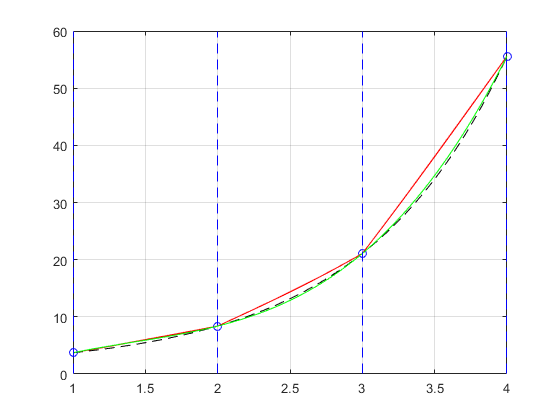


% Na koniec wyrysujmy naszą interpolację
fig=figure(1);
xx=linspace(min(x),max(x),401);
plot(x,y,'ob',xx,f(xx),'k--');grid on; hold on;
for i=x 
    xline(i, 'b--'); end;

s1=matlabFunction(S1);
s2=matlabFunction(S2);
s3=matlabFunction(S3);

xxx=[x(1):0.01:x(2)];
plot(xxx,s1(xxx),'r');
xxx=[x(2):0.01:x(3)];
plot(xxx,s2(xxx),'r');
xxx=[x(3):0.01:x(4)];
plot(xxx,s3(xxx),'r');hold on;

% Wrysujmy jeszcze wynik metody wbudowanej z MATLAB
xxx=[x(1):0.01:x(end)];
plot(xxx,spline(x,y,xxx),'g');

Choć wyniki obu splineów się różnią to możemy sprawdzić, że wszystkie wymagane przez nas założenia są spełnione:

% W sposób widoczny funkcja przechodzi przez punkty

% Drugie pochodne w węzłach są sobie równe:
% - dla wzła 2
subs(diff(S1,2),x(2))

$$ans = 0.6858$$

subs(diff(S2,2),x(2))

$$ans = 0.6858$$


% - dla węzła 3
subs(diff(S2,2),x(3))

$$ans = 5.2826$$

subs(diff(S3,2),x(3))

$$ans = 5.2826$$


% Dodatkowo druga pochodna w węzłach skrajnych jest równa 0
subs(diff(S1,2),x(1))

$$ans = 0$$

subs(diff(S3,2),x(end))

$$ans = 0$$

Różnica wynika z faktu, że domyślny spline w MATLAB to spline z warunkiem brzegowym "not a knot". Zwróć uwagę jak bardzo w takim przypadku wpływa to na wynik interpolacji (choć w dużej mierze jest to spowodowane małą ilością przedziałów w naszym przykładzie).

**ĆWICZENIE**

**Dla spline kubicznego warunek brzegowy "not-a-knot" oznacza, że trzecie pochodne w punktach a i b (w przykładzie są to punkty x=1 i x=4) są sobie równe. Zmodyfikuj powyższy układ równań tak, aby uwzględnić ten warunek zamiast spline naturalnego i zobacz ja to wpłynie na wynik.**

**WYKROZYSTYWANE FUNKCJE**

function TDD = divdiff(X, Y)
%
% TDD = divdiff(X, Y)
%
% DIVDIFF
%   Newton's Method for Divided Differences.
%
%   The following formula is solved:
%       Pn(x) = f(x0) + f[x0,x1](x-x0) + f[x0,x1,x2](x-x0)(x-x1) + ...
%           + f[x0,x1,..,xn](x-x0)(x-x1)..(x-x[n-1])
%       where f[x0,x1] = (f(x1-f(x0))/(x1-x0)
%             f[x0,x1,..,xn] = (f[x1,..,xn]-f[x0,..,x_[n-1]])/(xn-x0)
%
% NOTE: f^(n+1)(csi)/(n+1)! aprox. = f[x0,x1,..,xn,x_[n+1]]
%
% Input::
%	X = [ x0 x1 .. xn ] - object vector
%	Y = [ y0 y1 .. yn ] - image vector
%
% Output:
%   TDD - table of divided differences
%
% Example:
%   TDD = divdiff( [ 1.35 1.37 1.40 1.45 ], [ .1303 .1367 .1461 .1614 ])
%
% Author:	Tashi Ravach
% Version:	1.0
% Date:     22/05/2006
%
% Źródło: https://www.mathworks.com/matlabcentral/fileexchange/28215-newton-s-method-for-divided-differences
% Copyright (c) 2010, Tashi Ravach
% All rights reserved.
% 
% Redistribution and use in source and binary forms, with or without
% modification, are permitted provided that the following conditions are
% met:
% 
%     * Redistributions of source code must retain the above copyright
%       notice, this list of conditions and the following disclaimer.
%     * Redistributions in binary form must reproduce the above copyright
%       notice, this list of conditions and the following disclaimer in
%       the documentation and/or other materials provided with the distribution
% 
% THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS"
% AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE
% IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE
% ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT OWNER OR CONTRIBUTORS BE
% LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR
% CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF
% SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS
% INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN
% CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE)
% ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE
% POSSIBILITY OF SUCH DAMAGE.
    if nargin ~= 2
        error('divdiff: invalid input parameters'); 
    end

    [ p, m ] = size(X); % m points, polynomial order <= m-1
    if p ~= 1 || p ~=size(Y, 1) || m ~= size(Y, 2)
        error('divdiff: input vectors must have the same dimension'); 
    end

    TDD = zeros(m, m);
    TDD(:, 1) = Y';
    for j = 2 : m
        for i = 1 : (m - j + 1)
            TDD(i,j) = (TDD(i + 1, j - 1) - TDD(i, j - 1)) / (X(i + j - 1) - X(i));
        end
    end

end

function [x,sum, difff] =  NewtonInterpol(xx,f,xxx)
    xStart = xx(1);
    xEnd = xx(end);
    x = xxx;
    n = length(xx);
    d=zeros(n);
    for k = 1 : n - 1
        d(k, 1) = (f(k+1) - f(k))/(xx(k+1) - xx(k));
    end
    for j = 2 : n - 1
        for k = 1 : n - j
            d(k, j) = (d(k+1, j - 1) - d(k, j - 1))/(xx(k+j) - xx(k));
        end
    end
    d=[xx' f' d];
    p1=d(1,2);
    s=1;
    for i=2:n
        s=s.*(x-xx(i-1));
        p1=p1+d(1,i+1).*s;
    end
    sum=p1;
    difff=d(1,end-1);
end